# Homework 5

**Name:** YOUR NAME HERE

**Due Date: **

clear, clc

## Problem #1 - Comparing Runge-Kutta methods

**SETUP FOR PROBLEM**

dydx1 = @(x,y) (8*x^2 + 9*x + 27)/y^4;
x01 = 1.9;

xrange1 = [0.4 2.8];

**a) Analytically**

syms y(x)
% set up symbolic differential equation
ode = diff(y,x) == (8*x^2+9*x+27)/y^4;
% set up initial condition
cond = y(0.4) == x01;

% solve initial value problem
yExact(x) = dsolve(ode,cond);
xVals1a = xrange1(1):0.01:xrange1(2);


**b) Using Euler's method**

h = 0.8;
xVals1b1 = xrange1(1):h:xrange1(2);

yEuler11 = zeros(size(xVals1b1));
yEuler11(1) = x01;

phi = dydx1(xVals1b1(1),yEuler11(1));
yEuler11(2) = yEuler11(1) + phi*h;

phi = dydx1(xVals1b1(2),yEuler11(2));
yEuler11(3) = yEuler11(2) + phi*h;

phi = dydx1(xVals1b1(3),yEuler11(3));
yEuler11(4) = yEuler11(3) + phi*h;
h = 0.4;
xVals1b2 = xrange1(1):h:xrange1(2);

yEuler12 = zeros(size(xVals1b2));
yEuler12(1) = x01;

phi = dydx1(xVals1b2(1),yEuler12(1));
yEuler12(2) = yEuler12(1) + phi*h;

phi = dydx1(xVals1b2(2),yEuler12(2));
yEuler12(3) = yEuler12(2) + phi*h;

phi = dydx1(xVals1b2(3),yEuler12(3));
yEuler12(4) = yEuler12(3) + phi*h;

phi = dydx1(xVals1b2(4),yEuler12(4));
yEuler12(5) = yEuler12(4) + phi*h;

phi = dydx1(xVals1b2(5),yEuler12(5));
yEuler12(6) = yEuler12(5) + phi*h;

phi = dydx1(xVals1b2(6),yEuler12(6));
yEuler12(7) = yEuler12(6) + phi*h;

**c) Using midpoint method**

h = 0.8;

xVals1c = xrange1(1):h:xrange1(2);

yMid1 = zeros(size(xVals1c));

yMid1(1) = x01;

slope = dydx1(xVals1c(1),yMid1(1));
midpoint = yMid1(1) + slope * h/2;
phi = dydx1(xVals1c(1)+h/2, midpoint);
yMid1(2) = yMid1(1) + phi*h;

slope = dydx1(xVals1c(2),yMid1(2));
midpoint = yMid1(2) + slope * h/2;
phi = dydx1(xVals1c(2)+h/2, midpoint);
yMid1(3) = yMid1(2) + phi*h;

slope = dydx1(xVals1c(3),yMid1(3));
midpoint = yMid1(3) + slope * h/2;
phi = dydx1(xVals1c(3)+h/2, midpoint);
yMid1(4) = yMid1(3) + phi*h;

**d) Using 4th-order Runge-Kutta**

[xVals1d,yRK4] = rk4sys(dydx1,xrange1,1.9,0.8);

**e) Plot of results**

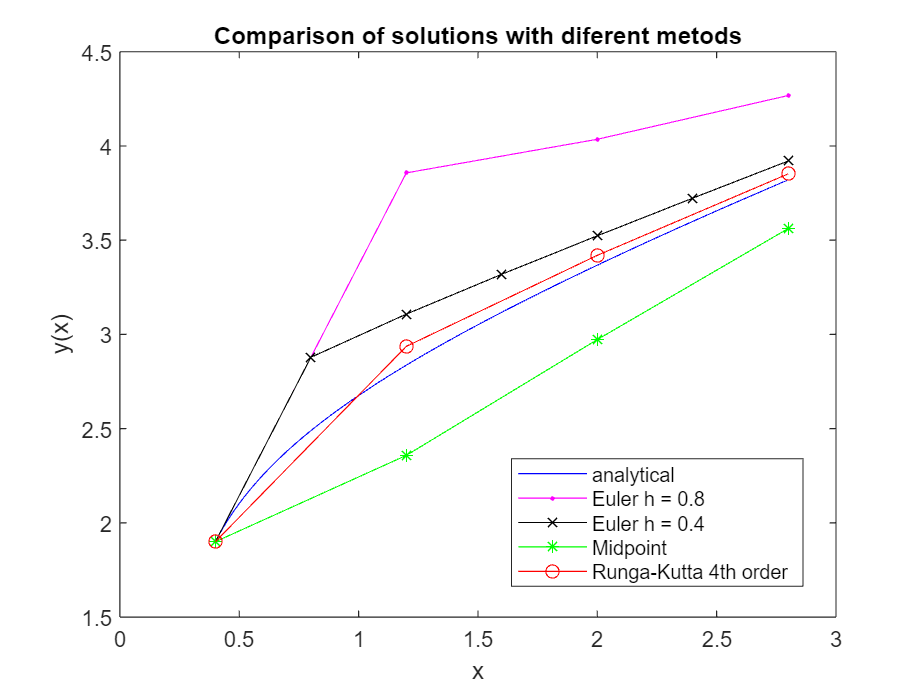

plot(xVals1a,yExact(xVals1a),'b',xVals1b1,yEuler11,'-m.',xVals1b2,yEuler12,'-kX',xVals1c,yMid1,'-g*',xVals1d,yRK4,'-ro')
legend('analytical','Euler h = 0.8','Euler h = 0.4','Midpoint','Runga-Kutta 4th order','Location','best')
title('Comparison of solutions with diferent metods')
xlabel('x')
ylabel('y(x)')

## Problem #2 - 4th order Runge-Kutta

**SETUP FOR PROBLEM**

dydt2 = @(t,x) 5*x - 2.3*exp(-t) - 0.6*t*x;
h = 0.2;
tRange1 = [4.5 5.5];
tVal1 = tRange1(1):h:tRange1(2);
rk41 = zeros(size(tVal1));
k = zeros(1,4);
rk41(1) = 0.7;

i = 1;
k1(i) = dydt2(tVal1(i),rk41(i));
k2(i) = dydt2(tVal1(i)+h/2,rk41(i)+k1(i)*h/2);
k3(i) = dydt2(tVal1(i)+h/2,rk41(i)+k2(i)*h/2);
k4(i) = dydt2(tVal1(i)+h,rk41(i)+k3(i)*h);
phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
rk41(i+1) = rk41(i) + phi(i)*h;

i = 2;
k1(i) = dydt2(tVal1(i),rk41(i));
k2(i) = dydt2(tVal1(i)+h/2,rk41(i)+k1(i)*h/2);
k3(i) = dydt2(tVal1(i)+h/2,rk41(i)+k2(i)*h/2);
k4(i) = dydt2(tVal1(i)+h,rk41(i)+k3(i)*h);
phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
rk41(i+1) = rk41(i) + phi(i)*h;

i = 3;
k1(i) = dydt2(tVal1(i),rk41(i));
k2(i) = dydt2(tVal1(i)+h/2,rk41(i)+k1(i)*h/2);
k3(i) = dydt2(tVal1(i)+h/2,rk41(i)+k2(i)*h/2);
k4(i) = dydt2(tVal1(i)+h,rk41(i)+k3(i)*h);
phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
rk41(i+1) = rk41(i) + phi(i)*h;

i = 4;
k1(i) = dydt2(tVal1(i),rk41(i));
k2(i) = dydt2(tVal1(i)+h/2,rk41(i)+k1(i)*h/2);
k3(i) = dydt2(tVal1(i)+h/2,rk41(i)+k2(i)*h/2);
k4(i) = dydt2(tVal1(i)+h,rk41(i)+k3(i)*h);
phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
rk41(i+1) = rk41(i) + phi(i)*h;

i = 5;
k1(i) = dydt2(tVal1(i),rk41(i));
k2(i) = dydt2(tVal1(i)+h/2,rk41(i)+k1(i)*h/2);
k3(i) = dydt2(tVal1(i)+h/2,rk41(i)+k2(i)*h/2);
k4(i) = dydt2(tVal1(i)+h,rk41(i)+k3(i)*h);
phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
rk41(i+1) = rk41(i) + phi(i)*h;
i = 6;
k1(i) = dydt2(tVal1(i),rk41(i));
k2(i) = dydt2(tVal1(i)+h/2,rk41(i)+k1(i)*h/2);
k3(i) = dydt2(tVal1(i)+h/2,rk41(i)+k2(i)*h/2);
k4(i) = dydt2(tVal1(i)+h,rk41(i)+k3(i)*h);
phi(i) = 1/6*(k1(i)+2*k2(i)+2*k3(i)+k4(i));
rk41(i+1) = rk41(i) + phi(i)*h;

[t1,y1] = rk4sys(dydt2,tRange1,0.7,h);


fprintf(' i    t       k1       k2       k3       k4      phi        x\n-- ---- -------- -------- -------- -------- -------- --------\n %d %4.2f %8f %8f %8f %8f %8f %8f\n %d %4.2f %8f %8f %8f %8f %8f %8f\n %d %4.2f %8f %8f %8f %8f %8f %8f\n %d %4.2f %8f %8f %8f %8f %8f %8f\n %d %4.2f %8f %8f %8f %8f %8f %8f\n %d %4.2f %8f %8f %8f %8.5f %8f %8f',1,tVal1(1),k1(1),k2(1),k3(1),k4(1),phi(1),rk41(1),2,tVal1(2),k1(2),k2(2),k3(2),k4(2),phi(2),rk41(2),3,tVal1(3),k1(3),k2(3),k3(3),k4(3),phi(3),rk41(3),4,tVal1(4),k1(4),k2(4),k3(4),k4(4),phi(4),rk41(4),5,tVal1(5),k1(5),k2(5),k3(5),k4(5),phi(5),rk41(5),6,tVal1(6),k1(6),k2(6),k3(6),k4(6),phi(6),rk41(6))

 i    t       k1       k2       k3       k4      phi        x
-- ---- -------- -------- -------- -------- -------- --------
 1 4.50 1.584449 1.899797 1.970435 2.364191 1.948184 0.700000
 2 4.70 2.354489 2.790253 2.882635 3.415171 2.852573 1.089637
 3 4.90 3.402785 3.985363 4.101878 4.798200 4.062578 1.660151
 4 5.10 4.782951 5.535121 5.676529 6.555030 5.626880 2.472667
 5 5.30 6.536958 7.472672 7.637358 8.703975 7.576832 3.598043
 6 5.50 8.683396 9.801563 9.984943 11.22673 9.913857 5.113409

## Problem #3 - Mass-spring-damper system

**SETUP FOR PROBLEM**

c1 = 9.6;
c2 = 48;
c3 = 240;
m = 9;
k = 64;
x0 = [3 -1];
[t1,x1] = ode45(@massSpring, [0 22], x0, [], c1, m, k);
[t2,x2] = ode45(@massSpring, [0 22], x0, [], c2, m, k);
[t3,x3] = ode45(@massSpring, [0 22], x0, [], c3, m, k);

**a) Displacement vs. time plot**

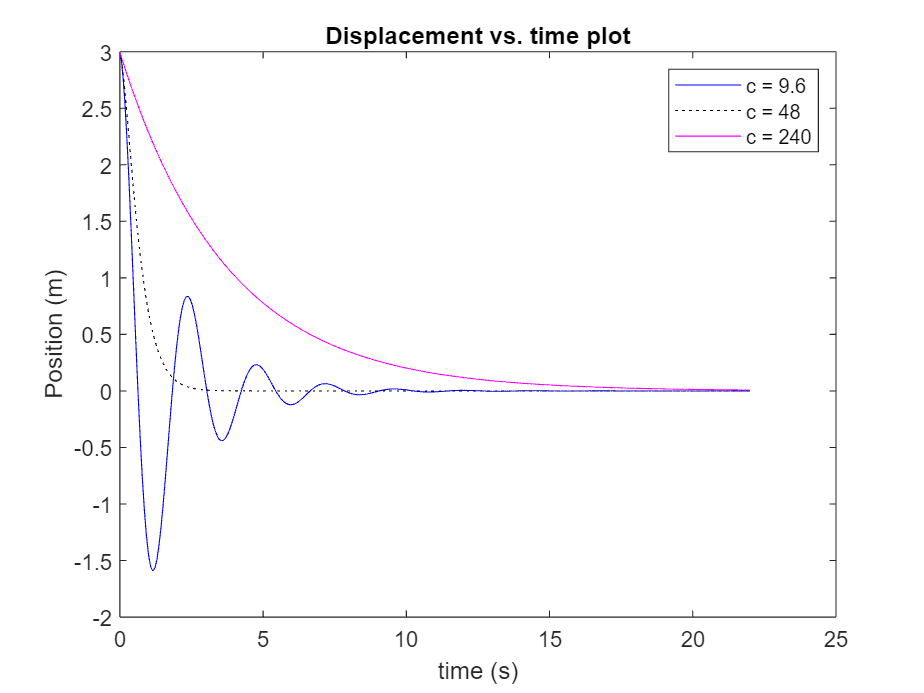

plot(t1,x1(:,1),'b',t2,x2(:,1),'k:',t3,x3(:,1),'m-')
xlabel 'time (s)'
ylabel 'Position (m)'
title 'Displacement vs. time plot'
legend('c = 9.6','c = 48','c = 240')

**b) Velocity vs. time plot**

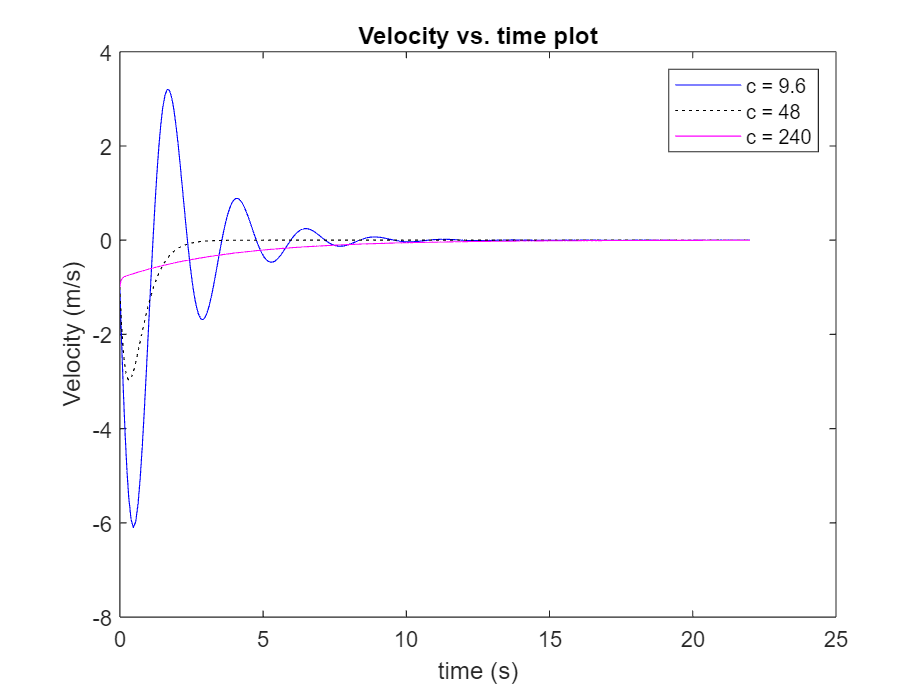

plot(t1,x1(:,2),'b',t2,x2(:,2),'k:',t3,x3(:,2),'m-')
xlabel 'time (s)'
ylabel 'Velocity (m/s)'
title 'Velocity vs. time plot'
legend('c = 9.6','c = 48','c = 240')

## Problem #4 - Euler-Cauchy

**SETUP FOR PROBLEM**

clf
h = 0.6;
xrange4 = [8 16.4];
xVals4 = xrange4(1):0.6:xrange4(2);

**a) Analytically**

syms y(x)
dy = diff(y);
ode = diff(y, x, 2) == -6/x*dy-6/(x^2)*y;
cond1 = y(8) == -4;
cond2 = dy(8) == 7;
conds = [cond1,cond2];
solution(x) = dsolve(ode,conds);

**b) Implicit Euler's **$Y_{i+1} ={\left(I-\textrm{Ah}\right)}^{-1} Y_i$

Yi1 = [-4 7];
xi(1) = 8;
for index = 2:15
xi(index) = (8+h*(index-1));
M = (eye(2)-[0 1;-6/(xi(index)^2) -6/xi(index)]*h);
Yi1(index,:) = M\Yi1(index-1,:)';
end
Yi1(end,:);

**c) ode23s**

[x23,y23] = ode23s(@secondOrderSystem,xrange4,[-4 7]);
y23(end,:);

**d) Plot of solutions**

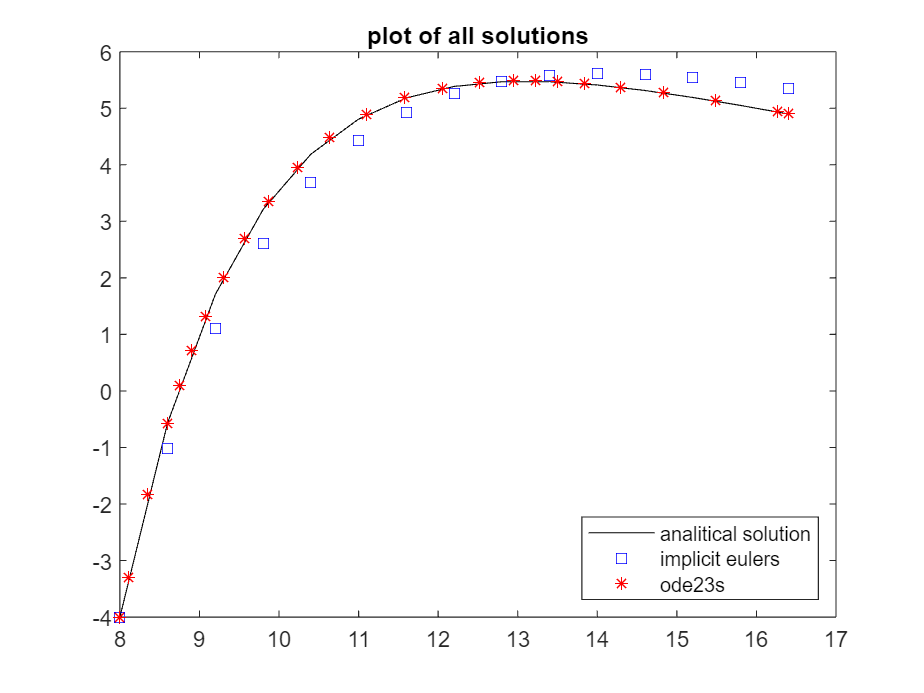

plot(xVals4,solution(xVals4),'k')
hold on
plot(xi,Yi1(:,1),'bsquare')
hold on
plot(x23,y23(:,1),'r*')
legend('analitical solution','implicit eulers','ode23s','Location','southeast')
title('plot of all solutions')

## Helper functions

### Problem #3 system function

function dX = massSpring(t,X,c,m,k)
dX = [X(2);
      -c/m*X(2)-k/m*X(1)];
end

### Problem #4 system function

function dY = secondOrderSystem(x,Y)

dY = [Y(2);-6/x*Y(2)-6/(x^2)*Y(1)];

end